## **Przetwarzanie Sygnałów Cyfrowych**

# **Parametry sygnalow cyfrowych**

## Jan Rosa 410269 AiR

### Zad 1

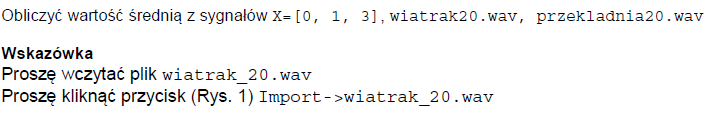

X = [0, 1, 3];
wiatrak20 = importdata('wiatrak_20.wav');
wiatrak20.t_vec = (0:size(wiatrak20.data)-1)/wiatrak20.fs;
przekladnia20 = importdata('przekladnia20.wav');
przekladnia20.t_vec = (0:size(przekladnia20.data)-1)/przekladnia20.fs;

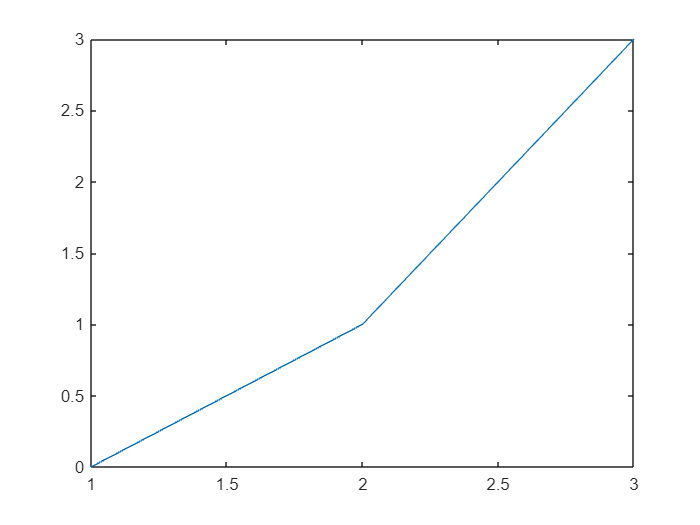

plot(X)

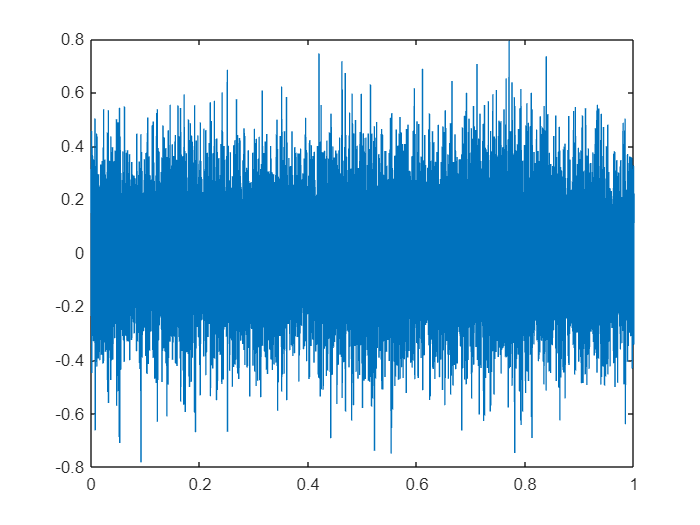

plot(wiatrak20.t_vec, wiatrak20.data)

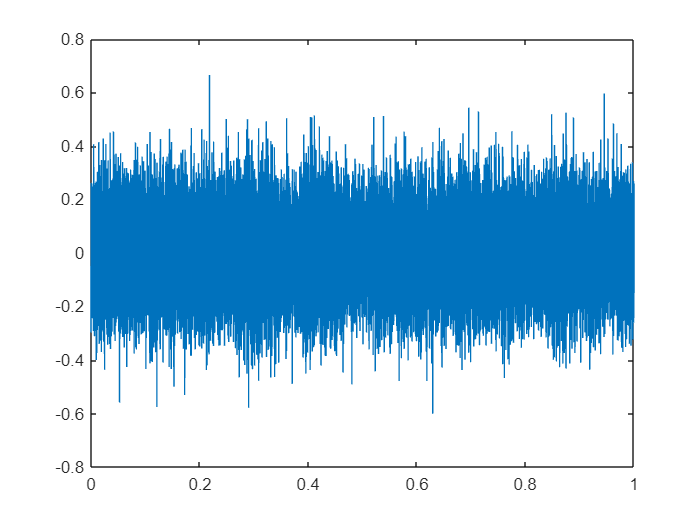

plot(przekladnia20.t_vec, przekladnia20.data)

mean(X)

ans = 1.3333

mean(wiatrak20.data)

ans = -2.4346e-05

mean(przekladnia20.data)

ans = -4.2175e-04

### Zad 2

rms(X)

ans = 1.8257

rms(wiatrak20.data)

ans = 0.1855

rms(przekladnia20.data)

ans = 0.1415

### Zad 3

peak2rms(X)

ans = 1.6432

peak2rms(wiatrak20.data)

ans = 4.2778

peak2rms(przekladnia20.data)

ans = 4.7018

### Zad 4

peak2peak(X)

ans = 3

peak2peak(wiatrak20.data)

ans = 1.5757

peak2peak(przekladnia20.data)

ans = 1.2662

### Zad 5

min(X)

ans = 0

min(wiatrak20.data)

ans = -0.7821

min(przekladnia20.data)

ans = -0.6008

max(X)

ans = 3

max(wiatrak20.data)

ans = 0.7936

max(przekladnia20.data)

ans = 0.6654

### Zad 6

var(X)

ans = 2.3333

var(wiatrak20.data)

ans = 0.0344

var(przekladnia20.data)

ans = 0.0200

### Zad 7

std(X)

ans = 1.5275

std(wiatrak20.data)

ans = 0.1855

std(przekladnia20.data)

ans = 0.1415

### Zad 8

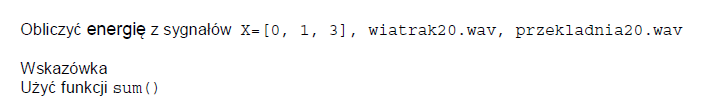

sum(power(X, 2))

ans = 10

sum(power(wiatrak20.data, 2))

ans = 1.5179e+03

sum(power(przekladnia20.data, 2))

ans = 883.1704

### Zad 9

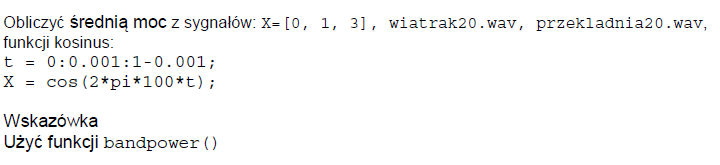

t = 0:0.001:1-0.001;
kosinus = cos(2*pi*100*t);
bandpower(X)

ans = 3.3333

bandpower(wiatrak20.data)

ans = 0.0344

bandpower(przekladnia20.data)

ans = 0.0200

bandpower(kosinus)

ans = 0.5000

### Zad 10

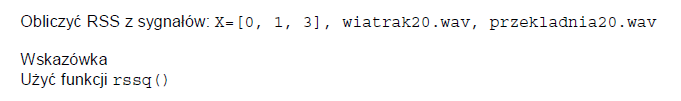

rssq(X)

ans = 3.1623

rssq(wiatrak20.data)

ans = 38.9602

rssq(przekladnia20.data)

ans = 29.7182

### Zad 11

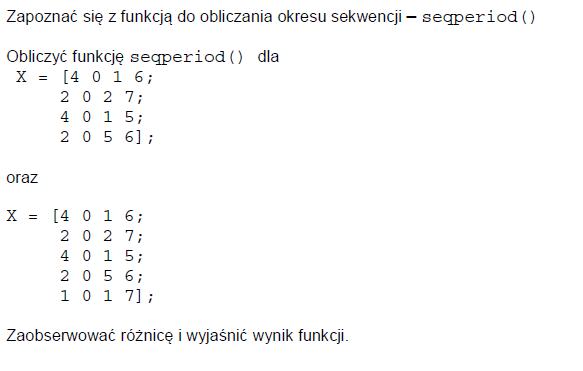

X1 =   [4 0 1 6;
        2 0 2 7;
        4 0 1 5;
        2 0 5 6];
seqperiod(X1)

ans =      2     1     4     3


X2 =   [4 0 1 6;
        2 0 2 7;
        4 0 1 5;
        2 0 5 6;
        1 0 1 7];
seqperiod(X2)

ans =      5     1     4     3


Wylicza okres wielokanałowego sygnału cyfrowego, okresy wyliczone na podstawie obu macierzy dodatkowe wartości w macierzy drugiej spowodowały przeliczenie okresu z 2 do 5 przez dodatkową wartość 1. 

### Zad 12

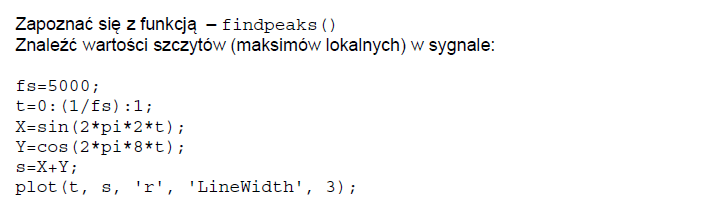

fs=5000;
t=0:(1/fs):1;
X=sin(2*pi*2*t);
Y=cos(2*pi*8*t);
s=X+Y;
figure
pks = findpeaks(s)

pks =     1.0314    2.0000    1.0314         0    1.0314    2.0000    1.0314         0


### Zad 13

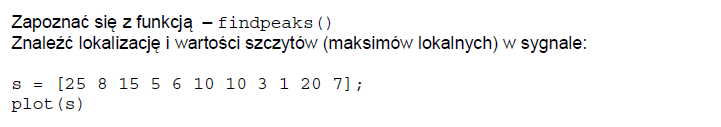

s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s)
[pks, locs] = findpeaks(s)

pks =     15    10    20


locs =      3     6    10


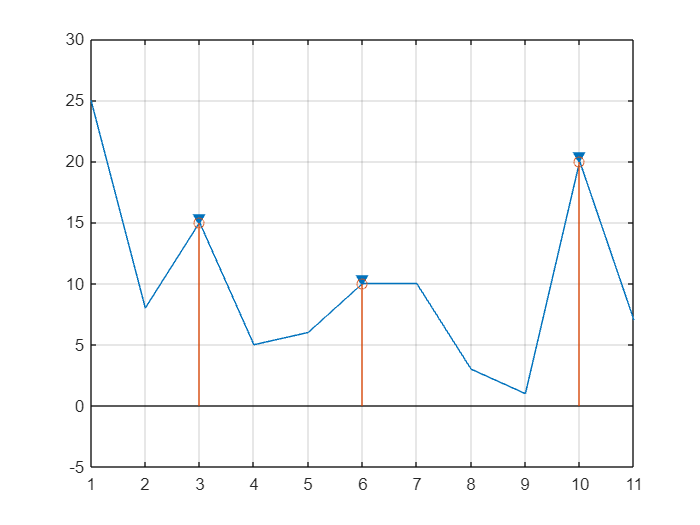

hold on;
stem(locs, pks);
hold off;

### Zad 14

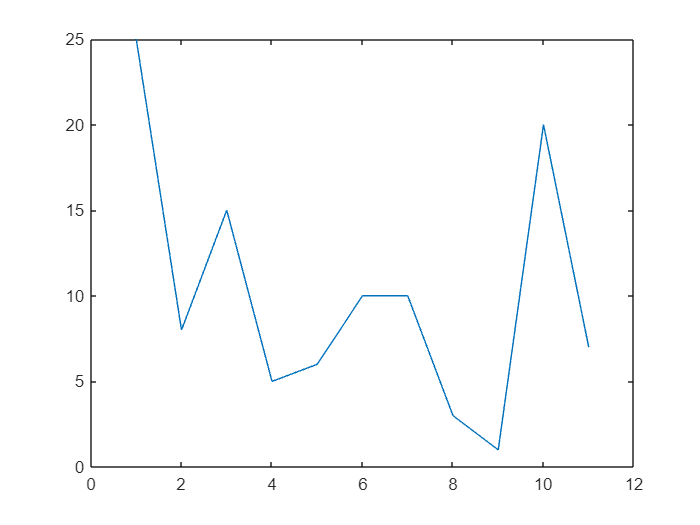

s = [25 8 15 5 6 10 10 3 1 20 7];
plot(s);

[PEAKS_s, lokalizacja]= findpeaks(s, 'SortStr','descend')

PEAKS_s =     20    15    10


lokalizacja =     10     3     6


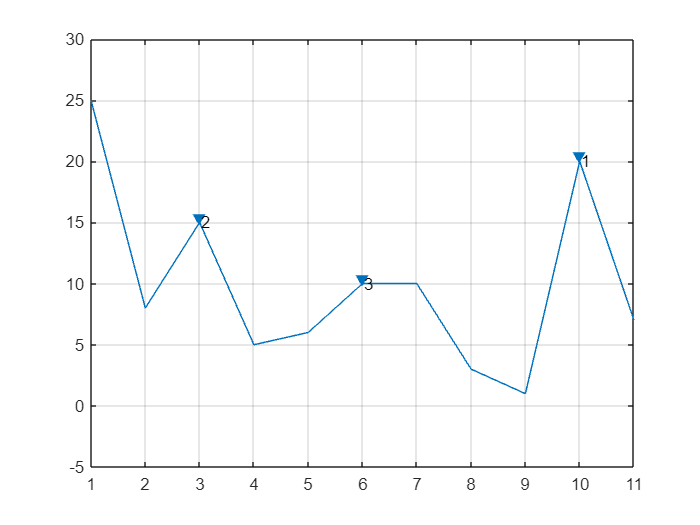

findpeaks(s, 'SortStr','descend')
text(lokalizacja +.02, PEAKS_s,num2str((1:numel(PEAKS_s))'))

### Zad 15

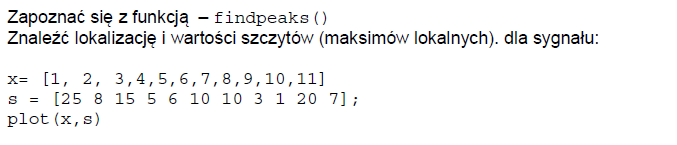

x= [1, 2, 3,4,5,6,7,8,9,10,11];
s = [25 8 15 5 6 10 10 3 1 20 7];
plot(x,s)

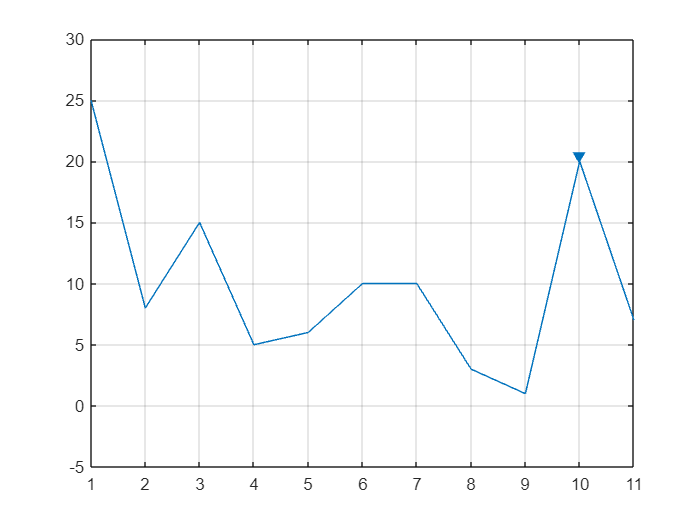

findpeaks(s, 'Threshold', 10)

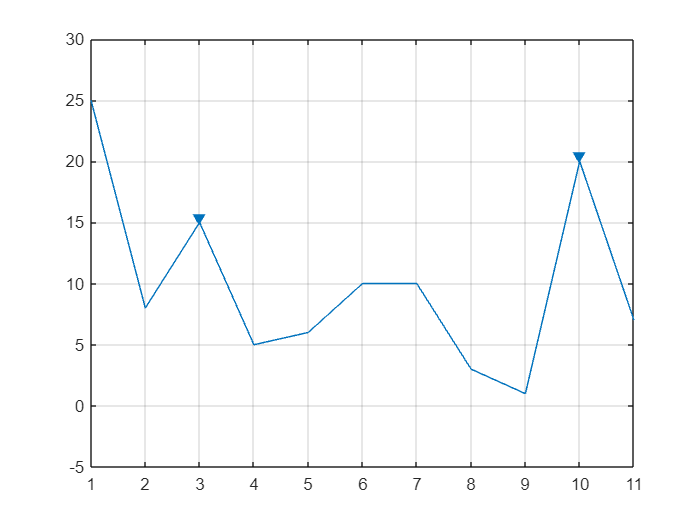

findpeaks(s, 'Threshold', 5)

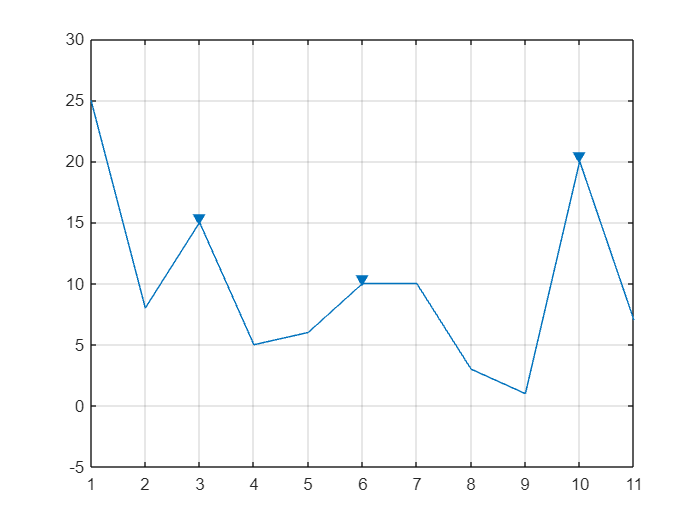

findpeaks(s, 'Threshold', 0)

Parametr Threshold ustawia minimalną wartość dla wykrywania peaków wględem sąsiednich wartości

### Zad 16

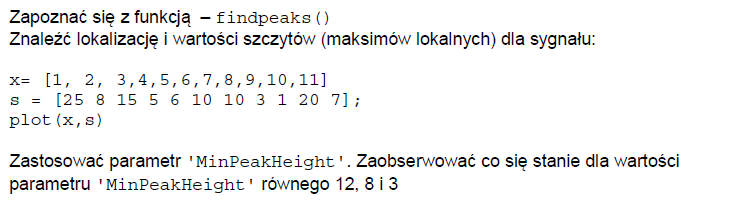

x= [1, 2, 3,4,5,6,7,8,9,10,11]

x =      1     2     3     4     5     6     7     8     9    10    11


s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s, 'MinPeakHeight', 12);

findpeaks(s, 'MinPeakHeight', 8);

findpeaks(s, 'MinPeakHeight', 3);

Parametr Threshold ustawia minimalną bezwzględną wartość dla wykrywania peaków

### Zad 17

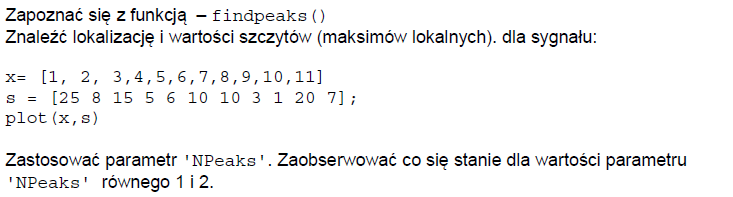

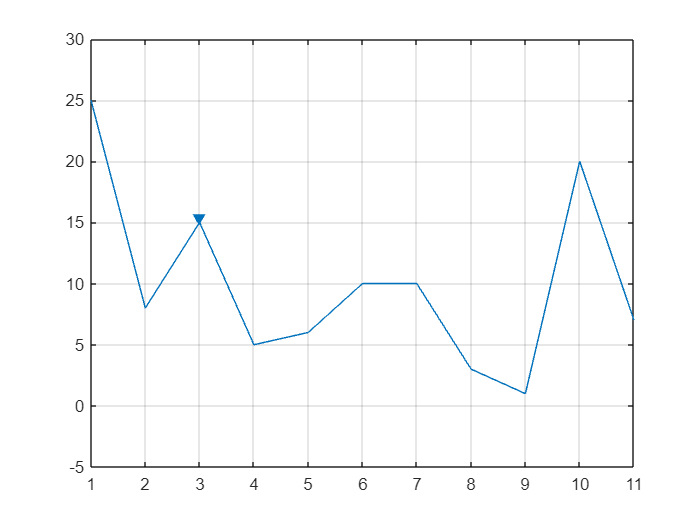

s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s, 'NPeaks', 1);

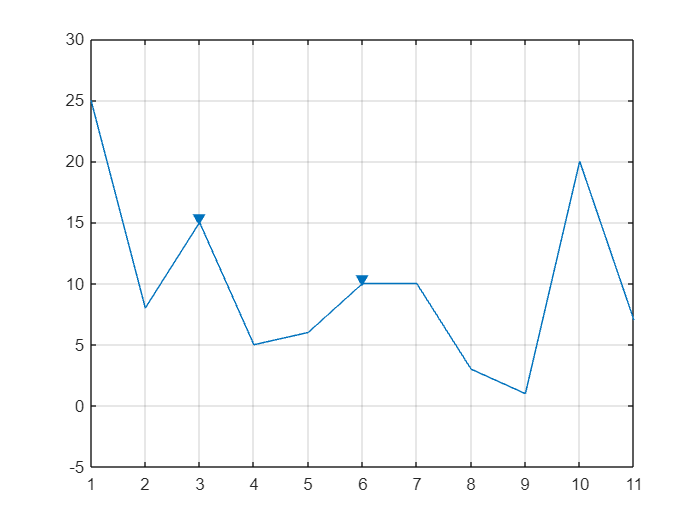

findpeaks(s, 'NPeaks', 2);

Ogranicza wyszukiwanie wieszchołków do N pierwszych

### Zad 18

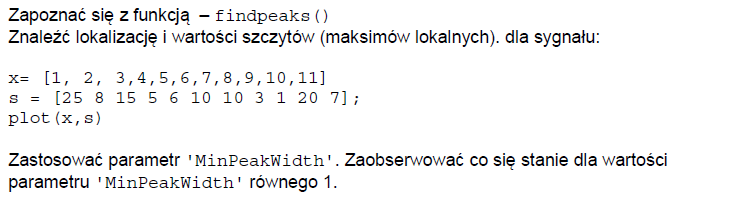

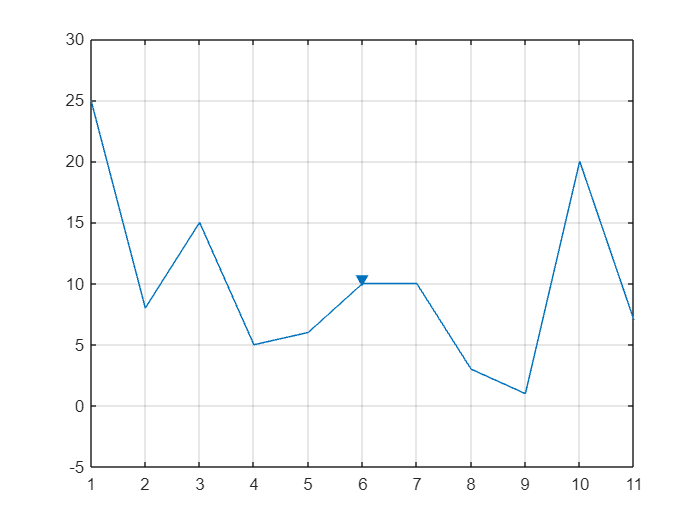

s = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(s, 'MinPeakWidth', 1)

### Zad 19

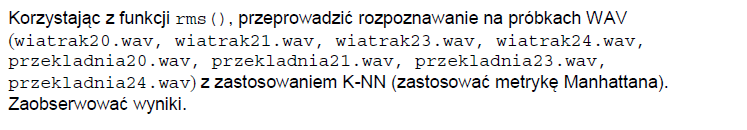

wiatrak21 = importdata('wiatrak_21.wav');
wiatrak23 = importdata('wiatrak_23.wav');
wiatrak24 = importdata('wiatrak_24.wav');
przekladnia21 = importdata('przekladnia21.wav');
przekladnia23 = importdata('przekladnia23.wav');
przekladnia24 = importdata('przekladnia24.wav');

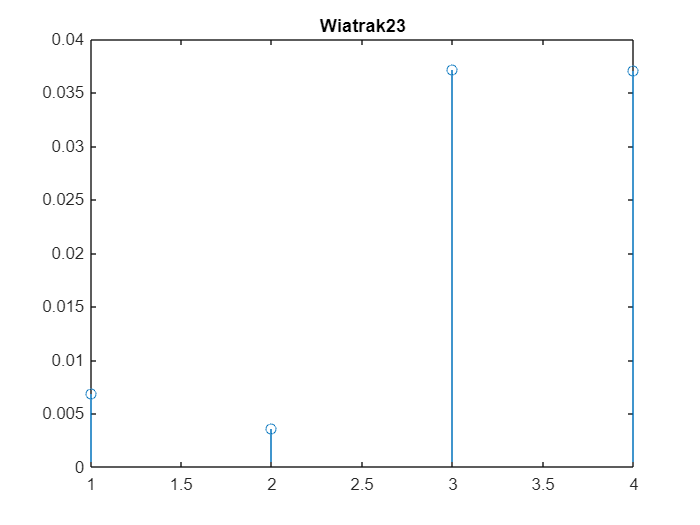

D = [];
D(1)=sum(abs(rms(wiatrak23.data) - rms(wiatrak20.data)));
D(2)=sum(abs(rms(wiatrak23.data) - rms(wiatrak21.data)));
D(3)=sum(abs(rms(wiatrak23.data) - rms(przekladnia20.data)));
D(4)=sum(abs(rms(wiatrak23.data) - rms(przekladnia21.data)));
stem(1:4,D)
title("Wiatrak23")

Należy do wiatraków

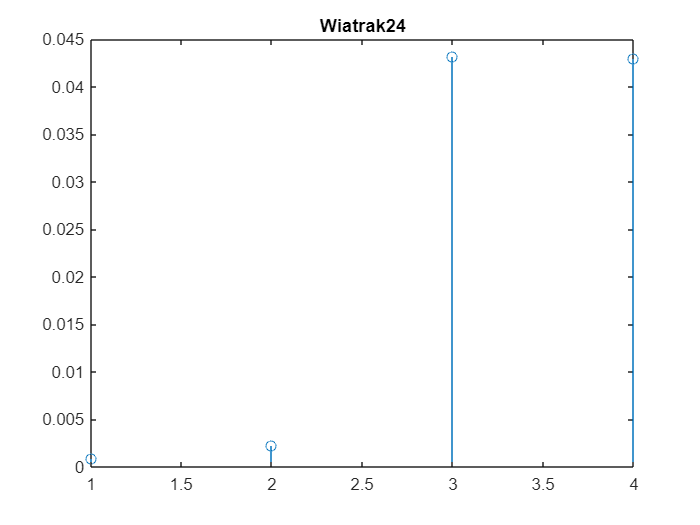

D = [];
D(1)=sum(abs(rms(wiatrak24.data) - rms(wiatrak20.data)));
D(2)=sum(abs(rms(wiatrak24.data) - rms(wiatrak21.data)));
D(3)=sum(abs(rms(wiatrak24.data) - rms(przekladnia20.data)));
D(4)=sum(abs(rms(wiatrak24.data) - rms(przekladnia21.data)));
stem(1:4,D)
title("Wiatrak24")

Należy do wiatraków

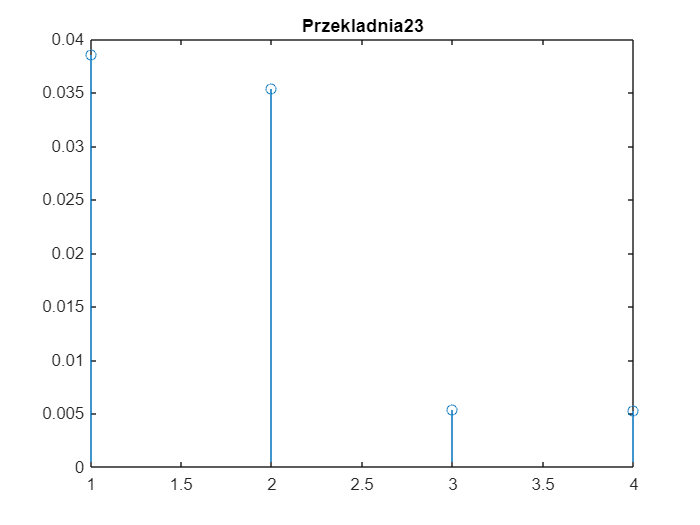

D = [];
D(1)=sum(abs(rms(przekladnia23.data) - rms(wiatrak20.data)));
D(2)=sum(abs(rms(przekladnia23.data) - rms(wiatrak21.data)));
D(3)=sum(abs(rms(przekladnia23.data) - rms(przekladnia20.data)));
D(4)=sum(abs(rms(przekladnia23.data) - rms(przekladnia21.data)));
stem(1:4,D)
title("Przekladnia23")

Należy do przekladni

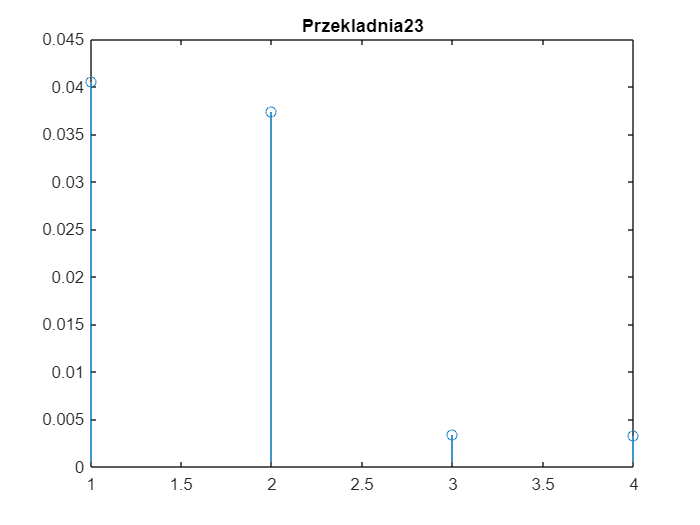

D = [];
D(1)=sum(abs(rms(przekladnia24.data) - rms(wiatrak20.data)));
D(2)=sum(abs(rms(przekladnia24.data) - rms(wiatrak21.data)));
D(3)=sum(abs(rms(przekladnia24.data) - rms(przekladnia20.data)));
D(4)=sum(abs(rms(przekladnia24.data) - rms(przekladnia21.data)));
stem(1:4,D)
title("Przekladnia23")

Należy do przekladni

### Pytania

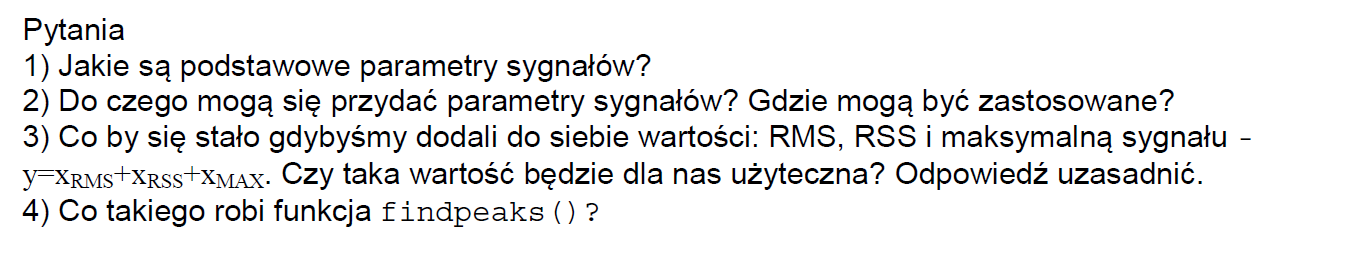

1) RMS, RSS, wariancja, średnia, wartość szczytu, współczynnik peak2peak, minimum i maksimum, odchylenie standardowe, energia, średnia moc.

2) Do analizy sygnałów, sprawdzaniu poprawności, np. kalibracji nagłośnienia koncertowego

3)Utracilibyśmy informacje o sygnale a niektóre informacje powiększyły by swoją wagę np. RMS wyprowadza się z RSS i mają podobne znaczenie

4)Znajduje maksima lokalne w wektorze, zwraca wektor wartości maksimów lokalnych oraz ich indeks z orginalnego wektora, może być konfugurowana aby zwracała maksima spełniające odpowiednie warunki.